# `Nonlinear Longitudinal Vehicle Model`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Autonomy in Vehicles ECE 5553  | Ohio State University | 2/20/2023`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents `

`1. Introduction `

`2. The Nonlinear Longitudinal Model`

`    a) Free Body Diagram ** `

`    c) Pure acceleration simulations `

`    d) Coast down simulations`

`        i) second order polynomial approximation`

`    e) Full brake simulations`

`        i) second order polynomial approximation`

`3. Conclusions and future work`

`4. Functions`

# `Introduction`

`    This report contains longitudinal vehicle modeling work formatted as a markdown file. Code, written in MATLAB, is contained in this file to run SIMULINK models, which must be downloaded separtely, if contained in the correctly named folder in the workspace path, no changes are necessary to repeat the same results. This report includes projects from the following Ohio State University courses: Vehicle Systems and Control Mechanical Engineering (ME) 8352 and Autonomy in Vehicles Electical and Computer Engineering (ECE) 5553 offered and completed by Brian Lesko in Autumn 2022 and Spring 2023 respectively in person at Ohio State's Columbus Campus. Topics covered in this report are partly inspired by these courses as well as the book Robust Controls of Mechatronic Systems by Dr. Levent Guvenc. `

#### Longitudinal Vehicle Model Top Level Diagram 

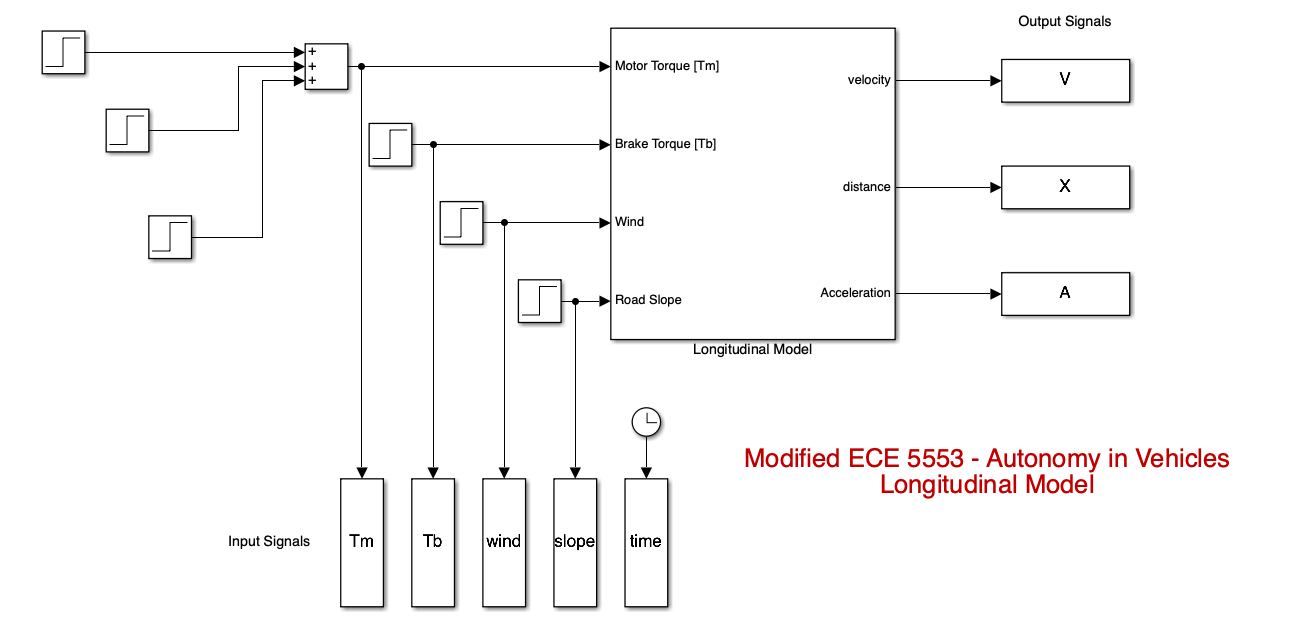

The step signals are added to create the desired motor torque commands in the following situations where the velocity over time is taken to be the output of the simulation

#### Vehicle Model Diagram

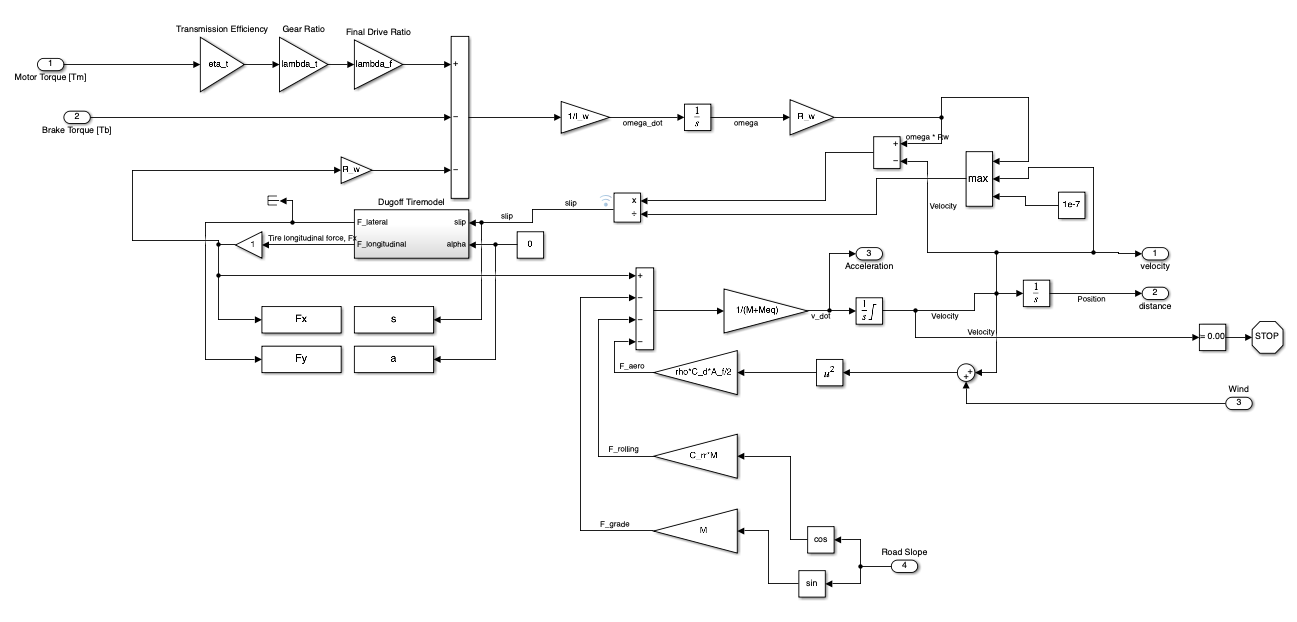

The duggoff Tire model can be viewed separately

clc; clear; close all;

# Pure Acceleration Simulations

To model the experimental transfer function with a simpler model, ignoring engine dynamics

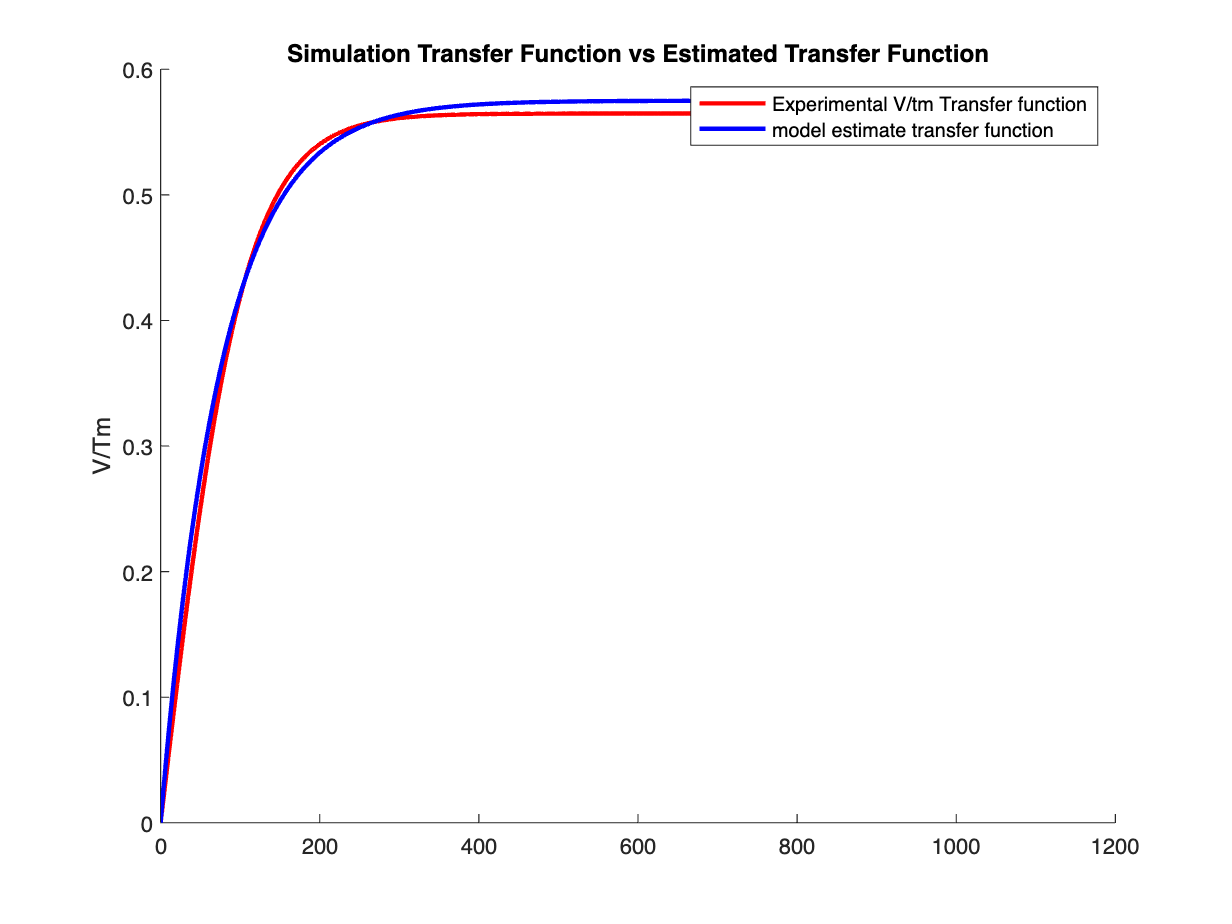

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
motorStart = 75;
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')
figure, hold on
K = 0.575;
T = 76;   	
plot(time,V./Tm,'r','linewidth',2)

s = tf('s');
V_tf = K/ (T*s + 1);

[h,g] = step(V_tf);
plot(g, squeeze(h), 'b','LineWidth',2)

legend('Experimental V/tm Transfer function','model estimate transfer function')
title('Simulation Transfer Function vs Estimated Transfer Function')
ylabel('V/Tm')

The simulated velocity curve can be matched well by manually fitting the model coefficients. However, this is for specific road conditions and specific vehicle commands, how much can this velocity profile vary?

## Running and recording simulation data

% unchanging Sim parameters for pure acceleration
[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

n=10;
for i = 1:1:n
    step = 20;
    motorStart = i*step;
    % Create a Sim Name
    ID = ['pureAcceleration_', num2str(i)]; % this is a cell, which contains text
    sim('longitudinal_model')

    % reduce samples to length b
    b = round(max(time)*3); % samples per second of sim time

    names = {'IDvec','time','Tm','Tb','X','V','A','wind','slope','mu'};
    time = sampVec(time, b); Tm = sampVec(Tm, b); Tb = sampVec(Tb, b); X = sampVec(X, b); V = sampVec(V, b); A = sampVec(A, b);
    wind = sampVec(wind, b); mu = sampVec(mu, b); slope = sampVec(slope, b);
    IDvec = repmat(ID, b , 1);
    simResult = table(IDvec,time,Tm,Tb,X,V,A,wind,slope,mu, 'VariableNames', names);

    vehicleCellsAcceleration{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsAcceleration{i}.Properties.VariableDescriptions = varDescriptions;
end
accelerationSims = vertcat(vehicleCellsAcceleration{:,1});
writetable(accelerationSims, 'accelerationSims.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plotting

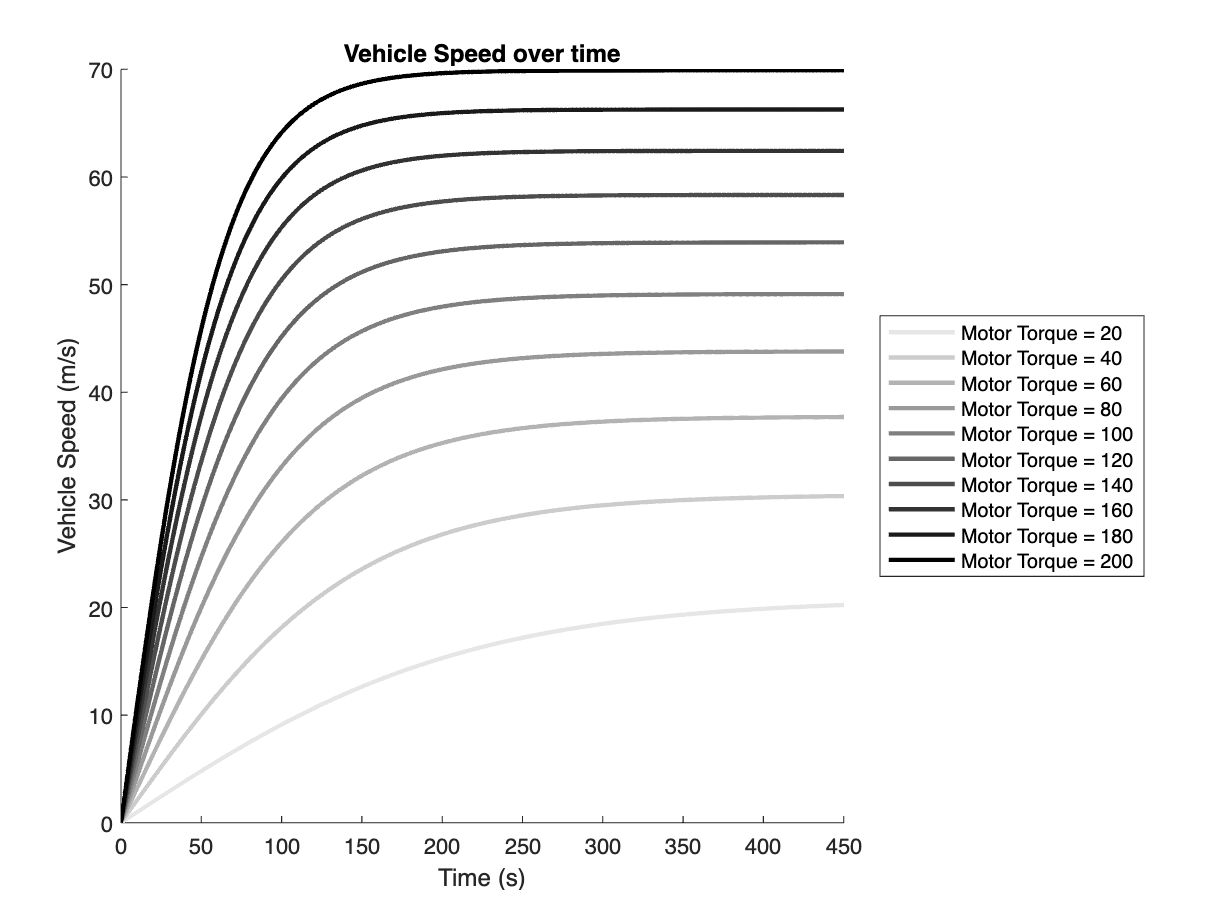

cmap = colormap(gray); close all
figure, hold on 
for i = 1:1:n
    % fetching the variables 
    time = vehicleCellsAcceleration{i}.time;
    V = vehicleCellsAcceleration{i}.V;
    Tm = vehicleCellsAcceleration{i}.Tm(1); % (1) because the motor torque is constant

    color = cmap(round(length(cmap)-256*Tm/(n*step+1)),:);
    plot(time,V,'r','linewidth',2,'Color',color);
    legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));

end 
title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)')
legend(legendInfo, 'Location', 'eastoutside')
xlim([0 450])

# Coast Down Simulations

Simulation scenario 3, step rise in motor torque, wait for speed to settle, then decrease motor torque to zero to record the coast down velocity profile. 

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

motorDecreaseTime = 300;

n=10;
for i = 1:1:n
    step = 20;
    motorStart = i*step;
    motorDecrease = motorStart;
    % Create a Sim Name
    ID = ['CoastDown_', num2str(i)]; % this is a cell, which contains text
    sim('longitudinal_model')

    % reduce samples to length b
    b = round(max(time)*2); % samples per second of sim time

    names = {'IDvec','time','Tm','Tb','X','V','A','wind','slope','mu'};
    time = sampVec(time, b); Tm = sampVec(Tm, b); Tb = sampVec(Tb, b); X = sampVec(X, b); V = sampVec(V, b); A = sampVec(A, b);
    wind = sampVec(wind, b); mu = sampVec(mu, b); slope = sampVec(slope, b);
    IDvec = repmat(ID, b , 1);
    simResult = table(IDvec,time,Tm,Tb,X,V,A,wind,slope,mu, 'VariableNames', names);

    vehicleCellsCoast{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsCoast{i}.Properties.VariableDescriptions = varDescriptions;
end
coastSims = vertcat(vehicleCellsCoast{:,1});
writetable(coastSims, 'coastSims.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plotting Coast Down

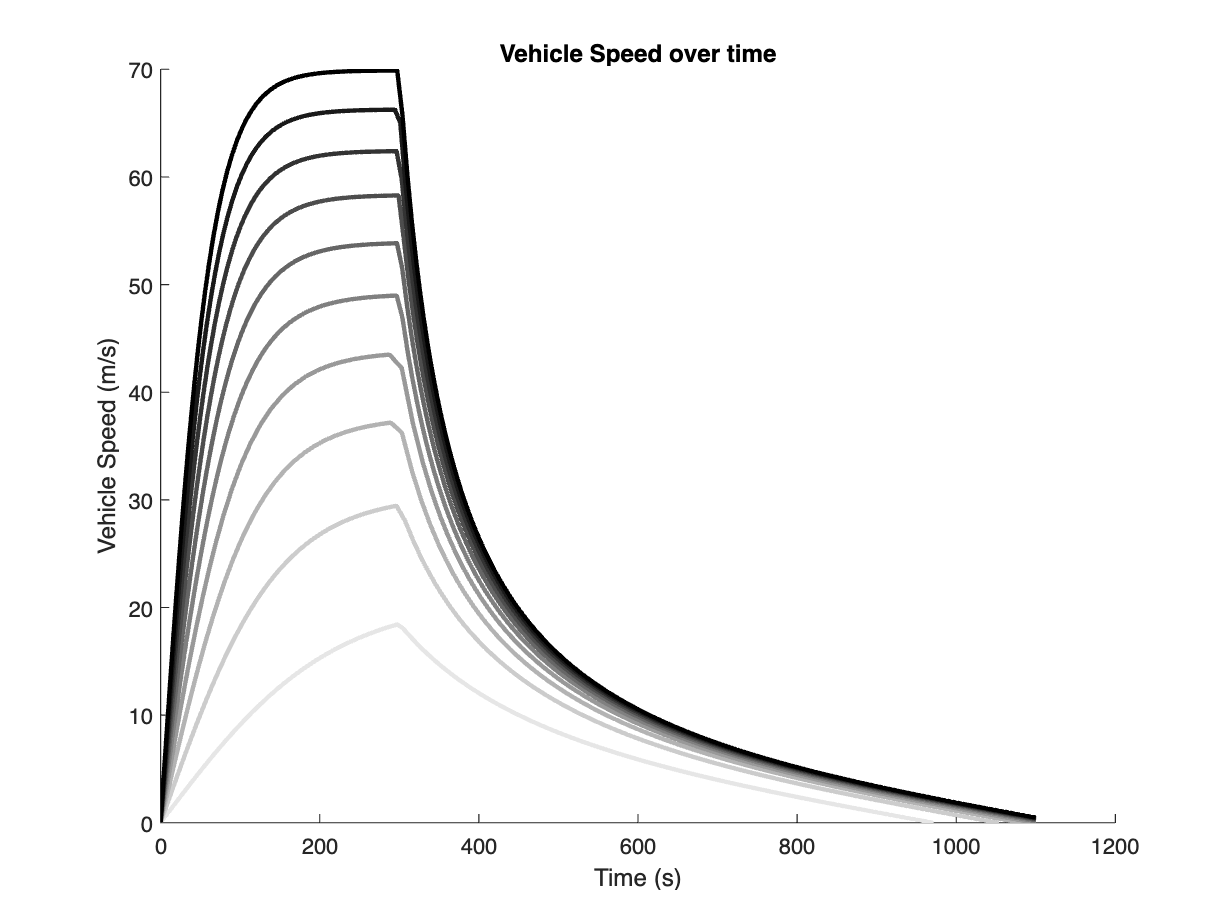

cmap = colormap(gray); close all
figure, hold on 
for i = 1:1:n
    % fetching the variables 
    time = vehicleCellsCoast{i}.time;
    V = vehicleCellsCoast{i}.V;
    Tm = vehicleCellsCoast{i}.Tm(1); % (1) because the motor torque is constant

    color = cmap(round(length(cmap)-256*Tm/(n*step+1)),:);
    plot(time,V,'r','linewidth',2,'Color',color);
    legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));

end 
title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)')

## Coast Down Approximation

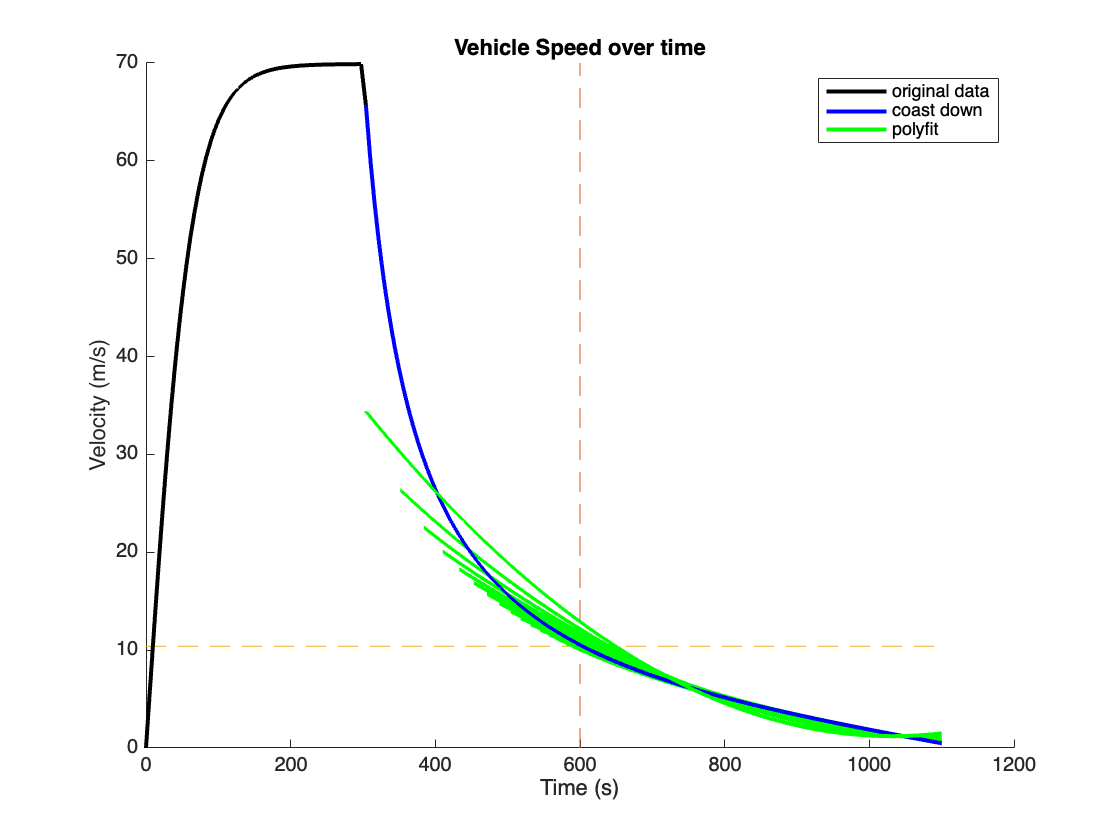

figure
hold on
extractFrom = 120;
for extractFrom = 800:-10:120
    len = length(time);
    extractTo = len;
    plta = plot(time,V,'k','linewidth',2);
    pltb = plot(time(extractFrom:extractTo),V(extractFrom:extractTo),'b','linewidt',2);
    p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
    x = time(extractFrom:extractTo);
    poly = p(1)*x.^2 + p(2)*x + p(3);
    pltc = plot(x,poly,'g','linewidth',2);
    if extractFrom == 270
        x = [600 600 600]; h = [0 100 1100];
        y = [0 50 70]; g = [10.4 10.4 10.4];
        plot(x,y,'--')
        plot(h,g,'--')
    end 
    drawnow
end 
legend('original data','coast down','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

A second order polynomial approximates the coast down velocity profile well for speeds below 10 m/s. Basis functions could be created to extend to higher speeds.

# Full Brake Simulations

Let Speed settle with a given Tm, then record the braking response

[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

motorDecreaseTime = 300;
brakeTime = 300;
breakStrength = 100;

n=10;
for i = 1:1:n
    step = 20;
    motorStart = i*step;
    motorDecrease = motorStart;
    % Create a Sim Name
    ID = ['CoastDown_', num2str(i)]; % this is a cell, which contains text
    sim('longitudinal_model')

    % reduce samples to length b
    b = round(max(time)*2); % samples per second of sim time

    names = {'IDvec','time','Tm','Tb','X','V','A','wind','slope','mu'};
    time = sampVec(time, b); Tm = sampVec(Tm, b); Tb = sampVec(Tb, b); X = sampVec(X, b); V = sampVec(V, b); A = sampVec(A, b);
    wind = sampVec(wind, b); mu = sampVec(mu, b); slope = sampVec(slope, b);
    IDvec = repmat(ID, b , 1);
    simResult = table(IDvec,time,Tm,Tb,X,V,A,wind,slope,mu, 'VariableNames', names);

    vehicleCellsBrake{i} = simResult;
    varDescriptions = {'vehicle ID','time (s)', 'motor torque (Nm)', 'brake torque (Nm)','position (m)','velocity (m/s)','acceleration (m/s^2)','headwind (N)','road slope (deg)','friction coefficient'};
    vehicleCellsBrake{i}.Properties.VariableDescriptions = varDescriptions;
end
brakeSims = vertcat(vehicleCellsBrake{:,1});
writetable(brakeSims, 'brakeSims.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plotting Brake Response

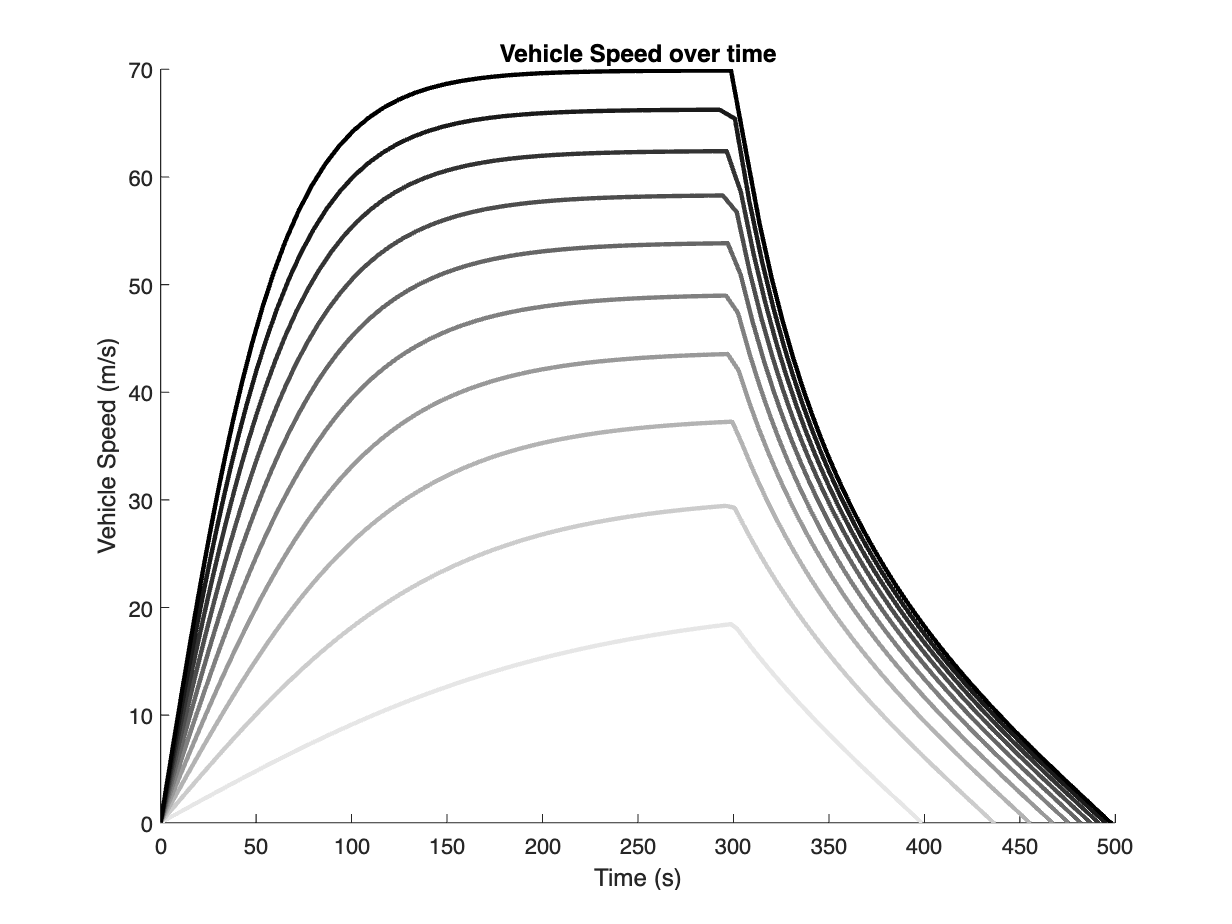

cmap = colormap(gray); close all
figure, hold on 
for i = 1:1:n
    % fetching the variables 
    time = vehicleCellsBrake{i}.time;
    V = vehicleCellsBrake{i}.V;
    Tm = vehicleCellsBrake{i}.Tm(1); % (1) because the motor torque is constant

    color = cmap(round(length(cmap)-256*Tm/(n*step+1)),:);
    plot(time,V,'r','linewidth',2,'Color',color);
    legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));

end 
title('Vehicle Speed over time'), xlabel('Time (s)'), ylabel('Vehicle Speed (m/s)')

Some data during the beginning of full brake has been lost, this can be seen from the cut corners.

## Full Brake Approximation

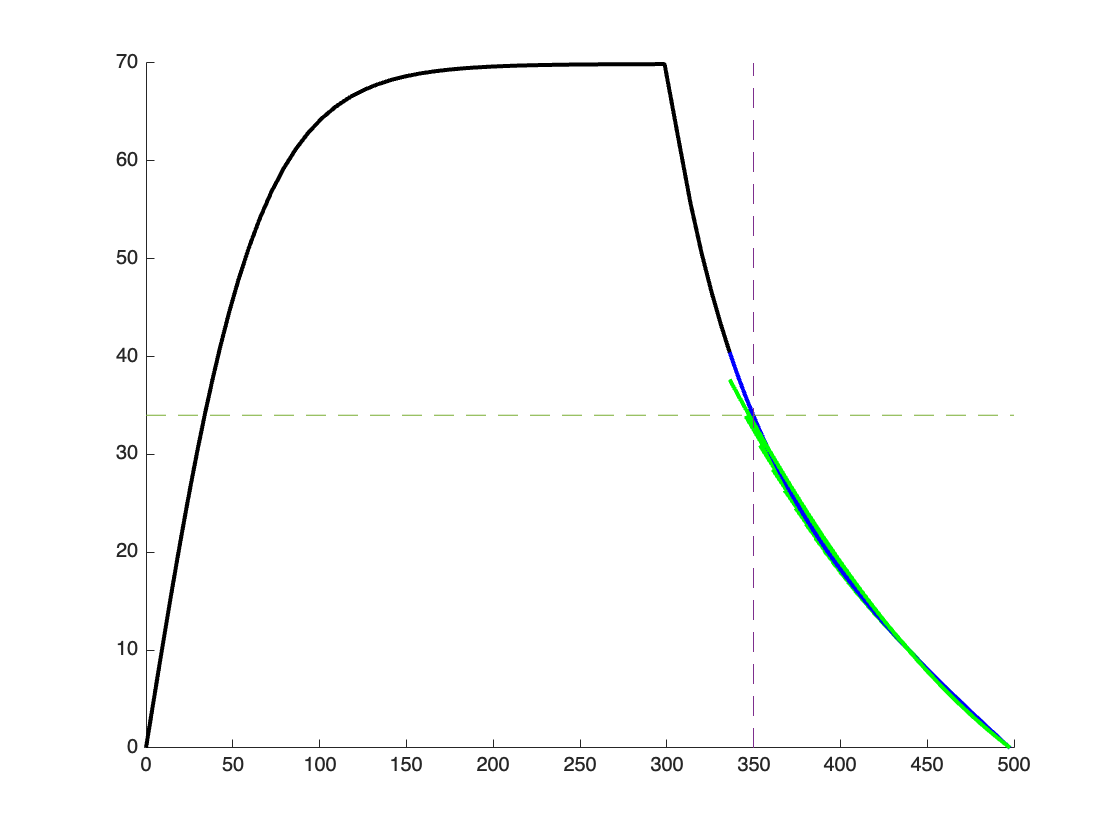

figure
hold on
for extractFrom = 300:-2:98
    len = length(time);
    extractTo = len;
    plta = plot(time,V,'k','linewidth',2);
    pltb = plot(time(extractFrom:extractTo),V(extractFrom:extractTo),'b','linewidt',2);
    p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
    x = time(extractFrom:extractTo);
    poly = p(1)*x.^2 + p(2)*x + p(3);
    pltc = plot(x,poly,'g','linewidth',2);
    if extractFrom == 104
        x = [350 350 350]; h = [0 100 500];
        y = [0 50 70]; g = [34 34 34];
        plot(x,y,'--')
        plot(h,g,'--')
    end 
    drawnow
end
legend('original data','coast down','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

The coast down profile can be approximated with a single second order polynomial for speeds below 34 m/s

# Headwind Simulation

Speed Settles, then headwind suddenly increases

figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 0;
motorDecreaseTime = 0;

brakeTime = 0;
breakStrength = 0;

headWindTime = 300;
headWind = 10;

roadSlopeTime = 0;
roadSlope = 0;

% Headwind increases to 10 at time 300

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

### Headwind Plotting

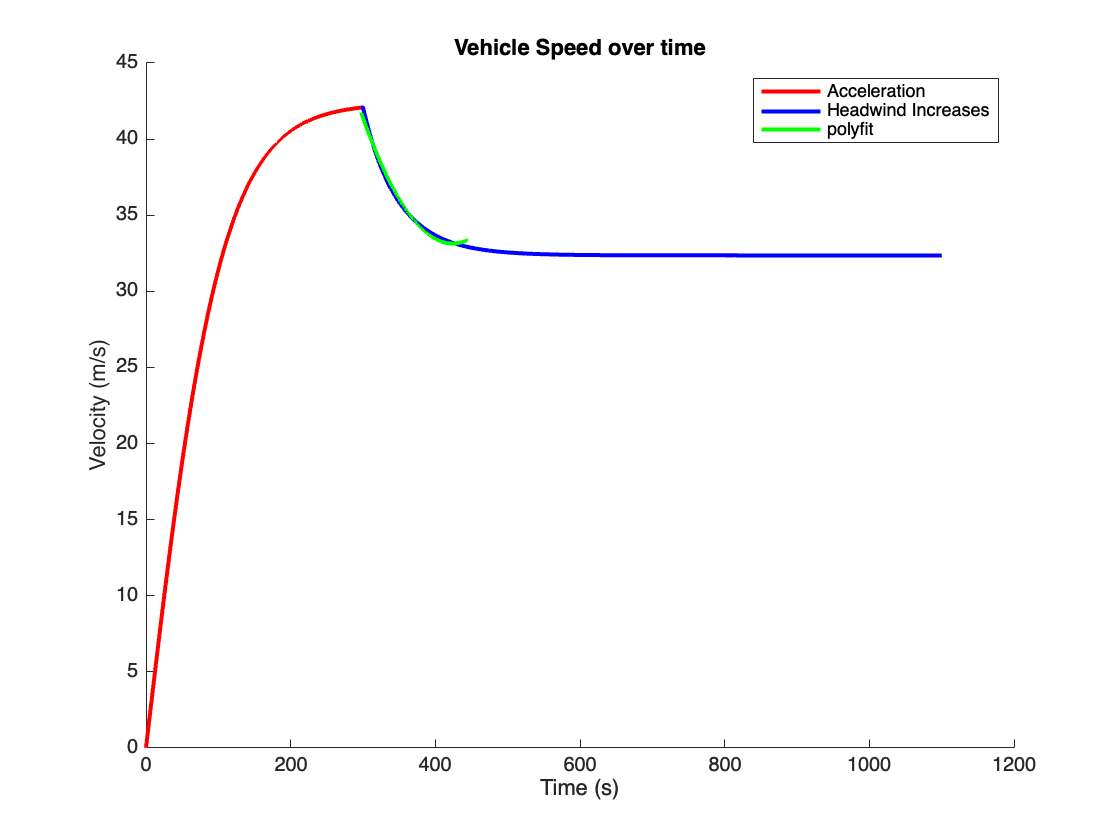

figure
hold on
extractFrom = 108000;
extractTo = 125000;
len = length(time);
plot(time,V,'r','linewidth',2)
plot(time(extractFrom:len),V(extractFrom:len),'b','linewidt',2)
p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
x = time(extractFrom:extractTo);
poly = p(1)*x.^2 + p(2)*x + p(3);
plot(x,poly,'g','linewidth',2)
legend('Acceleration','Headwind Increases','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

# Increasing road slope simulation

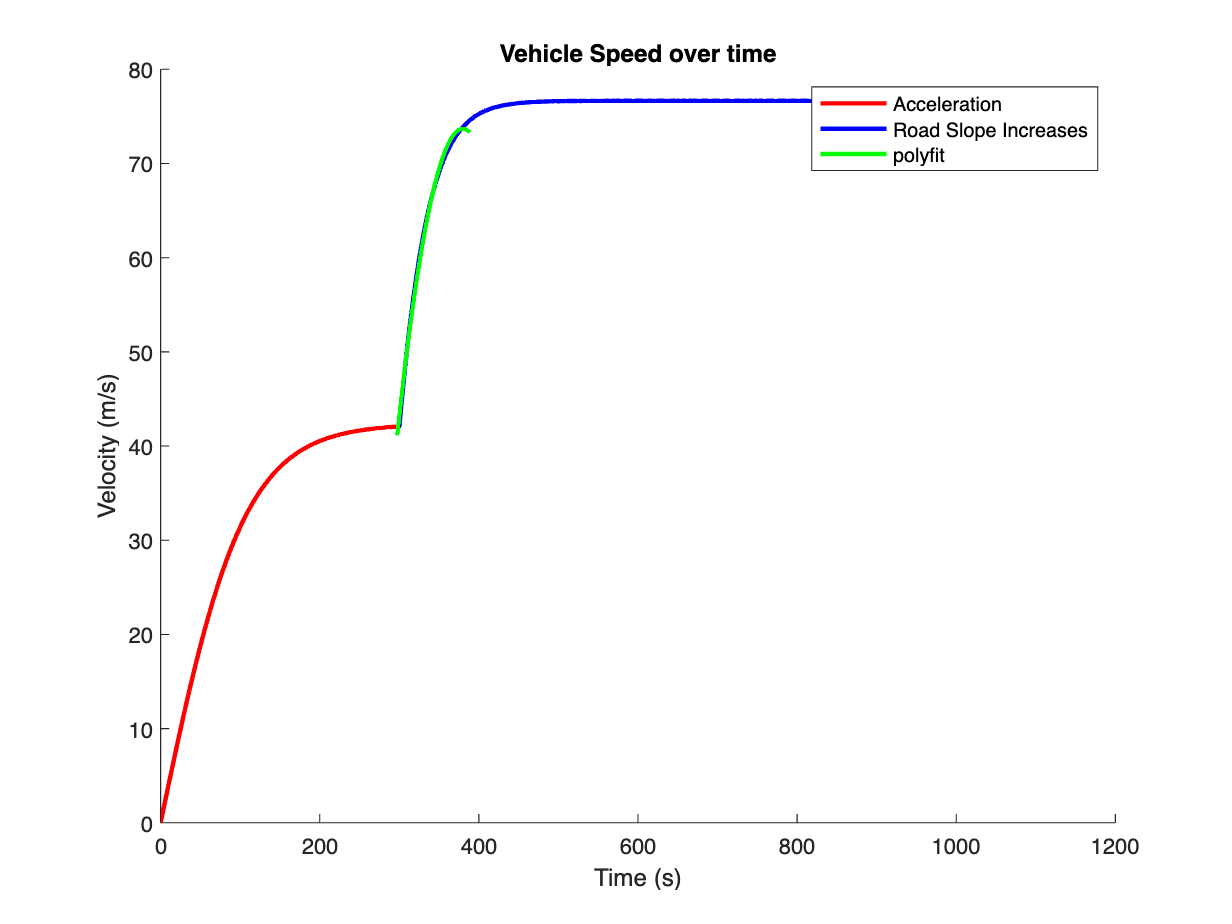

figure

motorStart = 75;
motorStartTime = 0;

motorIncrease = 0;
motorIncreaseTime = 0; 

motorDecrease = 0;
motorDecreaseTime = 0;

brakeTime = 0;
breakStrength = 0;

headWindTime = 0;
headWind = 0;

roadSlopeTime = 300;
roadSlope = 5;

% Road slope increases at time = 300 to alpha = 5

% Headwind increases to 10 at time 300

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();
sim('longitudinal_model')

figure
hold on
extractFrom = 108000;
extractTo = 114000;
len = length(time);
plot(time,V,'r','linewidth',2)
plot(time(extractFrom:len),V(extractFrom:len),'b','linewidt',2)
p = polyfit(time(extractFrom:extractTo),V(extractFrom:extractTo),2);
x = time(extractFrom:extractTo);
poly = p(1)*x.^2 + p(2)*x + p(3);
plot(x,poly,'g','linewidth',2)
legend('Acceleration','Road Slope Increases','polyfit')
xlabel('Time (s)'),ylabel('Velocity (m/s)'),title('Vehicle Speed over time')

A small increase in downhill road slope significantly increases vehicle speed for the same motor torque

function [M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters()
    M=2000; % Mass of the vehicle[Kg]
    eta_t=0.9; % Transmission Efficiency
    lambda_t=1.0; % Gear Ratio
    lambda_f=4.1; % Final Drive Ratio
    I_w=1; % Inertia of the Wheel[kgm2]
    R_w=0.3; % Wheel Radius[m]
    Meq=0.1*M; % Equivalent Mass Factor
    C_d=0.29; % Drag coefficient
    rho=1.225; % Air density[kg/m3]
    A_f=2.8;% Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.015;%Rolling resistance coefficient
    C_x=3e5; %Longitudinal Stiffness[N]
    C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad]
    L=2.85;% Wheelbase[m]
    l_f=1.3;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;% Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
end 
function [motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero()  
    motorStart = 0; motorStartTime = 0;
    motorIncrease = 0;motorIncreaseTime = 0; 
    motorDecrease = 0;motorDecreaseTime = 0;
    brakeTime = 0;breakStrength = 0;
    headWindTime = 0;headWind = 0;
    roadSlopeTime = 0;roadSlope = 0;
end 


function y = sampVec(x, b)
    % x: input vector
    % b: length of output vector
    
    a = length(x);
    y = linspace(1, a, b)';
    y = round(y);
    y = x(y);
end
